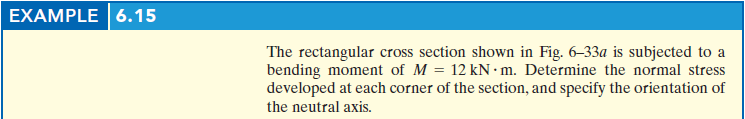

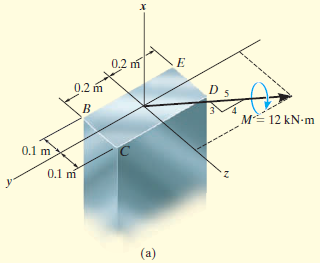

# symbolic units class

u = symunit;

# section properties

Iy = 0.4*0.2^3/sym(12)*u.m^4;
Iz = 0.2*0.4^3/sym(12)*u.m^4;

# bending moments

M = 12*u.kN*u.m;
My = -M*(4/5);
Mz = M*(3/5);

# bending moment locations

y = [0.2; 0.2; -0.2; -0.2]*u.m;
z = [-0.1; 0.1; 0.1; -0.1]*u.m;

# bending stress and neutral axis location

[sigma alpha] = beam.unsymmetric(My, Mz, Iy, Iz, y, z); %#ok
sigma = rewrite(sigma, u.MPa);
sigma_vpa = vpa(sigma) %#ok

$$sigma\_vpa = \left(\begin{array}{c} 2.25\,\mathrm{MPa}\\ -4.95\,\mathrm{MPa}\\ -2.25\,\mathrm{MPa}\\ 4.95\,\mathrm{MPa} \end{array}\right)$$

alpha_vpa = vpa(alpha, 3) %#ok

$$alpha\_vpa = -79.4\,\deg$$

clear sigma_vpa alpha_vpa;